# Optical flow analysis of focal adhesions

Inputs are Nikon .nd2 files (raw acquisition) and tif files (segmentation of the focal adhesions with Metamorph).

Nicolas Liaudet

Bioimaging Core Facility - UNIGE

[https://www.unige.ch/medecine/bioimaging/en/bioimaging-core-facility/](https://www.unige.ch/medecine/bioimaging/en/bioimaging-core-facility/)

v1.1 11-Mar-2020 NL

## Initialization

clc
clear all
close all
cd(fileparts(which('AdhesionFlow.mlx')))
addpath(genpath('mfiles'))
bfInitLogging();
try
    bfUpgradeCheck();
end

*** bioformats_package.jar is up-to-date ***


DefaultOptions = load([pwd filesep 'mfiles' filesep 'DefaultOptions.mat']);
DefaultOptions = DefaultOptions.DefaultOptions;
if isempty(gcp('nocreate'))
    parpool('IdleTimeout', 120);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


## Data selection and loading

[FileName,FolderPath] = uigetfile({'*.nd2','Nikon file (*.nd2)'},...
    'Select an acquisition file',...
    DefaultOptions.LastFolderPath,'MultiSelect', 'off');
if isnumeric(FolderPath)
    return
end
FolderPath = fileparts(FolderPath);
DATA = read_ND2(FolderPath,FileName);
if isempty(DATA)
    return
end
DATA.t.Format = 'mm:ss';
DefaultOptions.LastFolderPath = FolderPath;
save([pwd filesep 'mfiles' filesep 'DefaultOptions.mat'],'DefaultOptions')

[idxSelCh,tf] = listdlg('PromptString',{'Select the channel to be used'},'SelectionMode','single',...
    'ListString',DATA.ChannelName);
if ~tf
    return
end
% stack = DATA.OriginalStack(:,:,:,indx);


## Focal adhesions mask loading

maskPath = uigetdir(FolderPath);
fnames = dir(maskPath);
fnames = {fnames.name};
idxKeep = regexp(fnames,'(\d{4})_Mask.tif');
idxKeep= ~cellfun(@isempty,idxKeep);
fnames = fnames(idxKeep);
idxTmask = regexp(fnames,'\d{4}','Match');
idxTmask = str2double(cat(1,idxTmask{:}))+1;
[~,idxperm] = ismember([1:DATA.DimT],idxTmask);
idxTmask  = idxTmask(idxperm);
BWadhesion = false(DATA.DimY,DATA.DimX,DATA.DimT);
for idxT=1:DATA.DimT
    BWadhesion(:,:,idxT) = imread(fullfile(maskPath,fnames{idxTmask(idxT)}));
end
DATA.BWadhesion = BWadhesion;

## Data registration

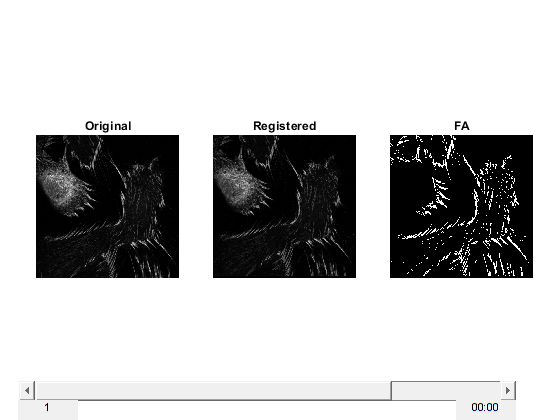

DefaultOptions.registration_para.idxTREF = floor(DATA.DimT/2);
DefaultOptions.registration_para.idxCREF = idxSelCh;
DefaultOptions.registration_para.sigmablur = 5;

[DATA.stack_reg,f] = par_stackreg(DATA,DefaultOptions.registration_para);
IM = {DATA.OriginalStack(:,:,:,idxSelCh); DATA.stack_reg(:,:,:,idxSelCh);uint8(f)};
MultipleDisplay([1 3],IM,{'Original','Registered','FA'},DATA.t);

## Data filtering

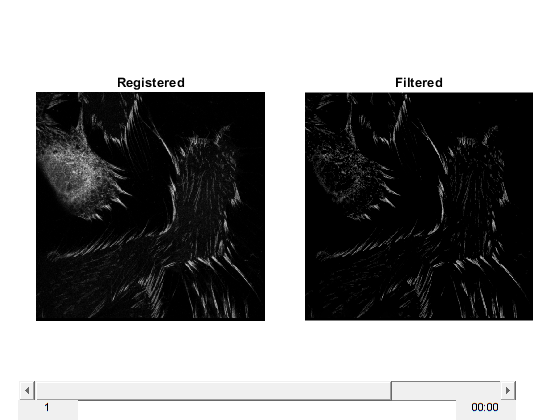

stack_filtered = DATA.stack_reg;
DimC = DATA.DimC;
WaitMessage = parfor_wait(DATA.DimT, 'Waitbar', true);
parfor idxF = 1:DATA.DimT
    WaitMessage.Send;
    for idxC = 1:DimC
        tmp = DATA.stack_reg(:,:,idxF,idxC);
        stack_filtered(:,:,idxF,idxC) = imnlmfilt(imsubtract(tmp,imgaussfilt(tmp,[20 20])));
    end
end
DATA.stack_filtered = stack_filtered;
WaitMessage.Destroy
IM = {DATA.stack_reg(:,:,:,idxSelCh); DATA.stack_filtered(:,:,:,idxSelCh)};
MultipleDisplay([1 2],IM,{'Registered','Filtered'},DATA.t);

## Optical Flow


flow = cell(DATA.DimT,DATA.DimC);
for idxC = 1:DATA.DimC
    try
        reset(opticFlow)
    catch ME
        
    end
    opticFlow = opticalFlowFarneback;
    imch = DATA.stack_filtered(:,:,:,idxC);
    frameGray = mat2gray(imch,double([min(imch(:)) max(imch(:))]));
        
    for idxF = 1:DATA.DimT
        
        flow{idxF,idxC} = estimateFlow(opticFlow,frameGray(:,:,idxF));
    end
    reset(opticFlow)
    
end

Error using opticalFlowFarneback
License checkout failed.
License Manager Error -4
Maximum number of users for Video_and_Image_Blockset reached. 
Try again later.

Troubleshoot this issue by visiting: 
<a href="https://www.mathworks.com/support/lme/R2020b/4">https://www.mathworks.com/support/lme/R2020b/4</a>

Diagnostic Information:
Feature: Video_and_Image_Blockset 
License path: C:\Users\liaudet\AppData\Roaming\MathWorks\MATLAB\R2020b_licenses;C:\Program Files\MATLAB\R2020b\licenses\license.dat;C:\Program Files\MATLAB\R2020b\licenses\network.lic 
Licensing error: -4,132.

DATA.flow = flow;

DATA.Orientation = zeros(DATA.DimY,DATA.DimX,DATA.DimT,DATA.DimC);
DATA.Magnitude   = zeros(DATA.DimY,DATA.DimX,DATA.DimT,DATA.DimC);
for idxC = 1:DATA.DimC
    Orientation = cellfun(@(x) x.Orientation,DATA.flow(:,idxC),'UniformOutput',false);
    Orientation = cat(3,Orientation{:});
    Orientation = -rad2deg(Orientation);
    DATA.Orientation(:,:,:,idxC) = Orientation;
    
    Magnitude = cellfun(@(x) x.Magnitude,DATA.flow(:,idxC),'UniformOutput',false);
    Magnitude = cat(3,Magnitude{:})*DATA.ResX;
    DATA.Magnitude(:,:,:,idxC) = Magnitude;
end

ShowFlow(DATA)







[~,fn] = fileparts(FileName);
save(fullfile(FolderPath,[fn,'.mat']),'DATA','-v7.3')

## Extraction of optical flow in focal adhesions

The values are extracted from t1 to t2 values are in minutes. 

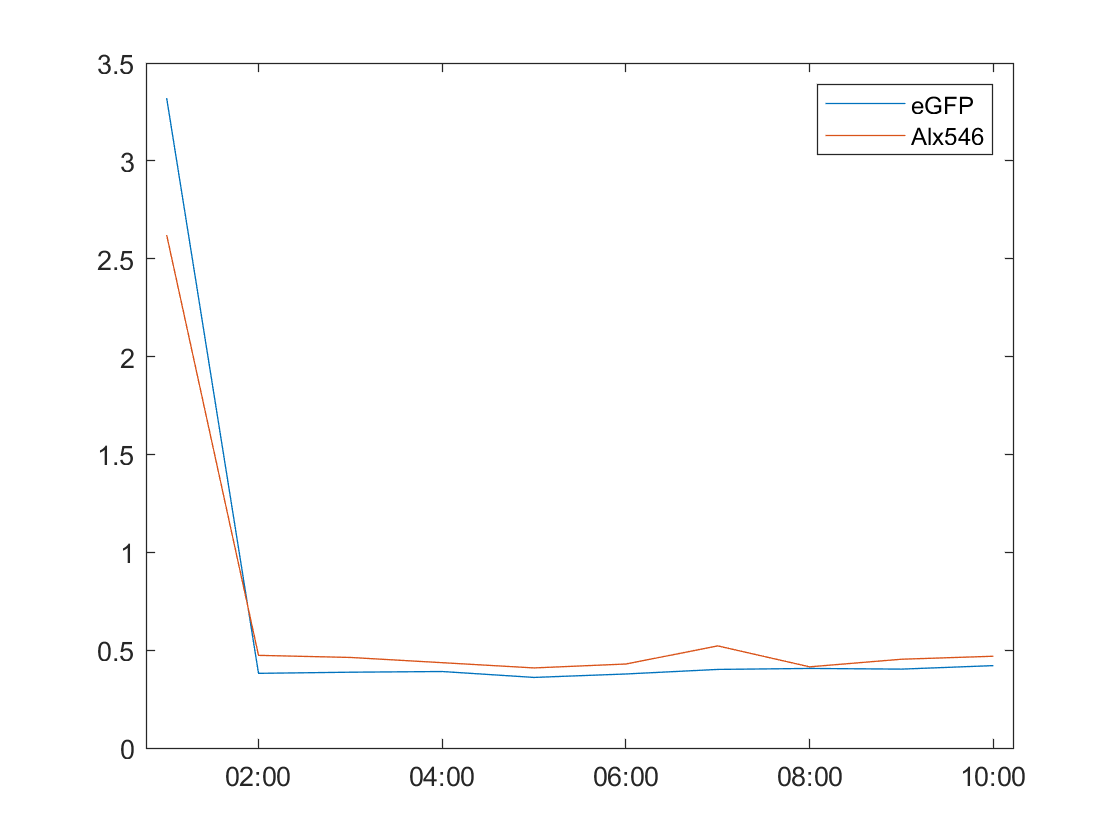

% t1 = 5;  %in minutes
% t2 = 10.5; %in minutes
% %____________________
% idxTwin = find(minutes(t1)<=DATA.t&DATA.t<=minutes(t2));
% speed_m = zeros(length(idxTwin),DATA.DimC);
% speed_s = zeros(length(idxTwin),DATA.DimC);
% for idxC = 1:DATA.DimC
% %     WaitMessage = parfor_wait(DATA.DimT, 'Waitbar', true);
%     for idxT=1:length(idxTwin)
% %         WaitMessage.Send;
%         mag = DATA.Magnitude(:,:,idxTwin(idxT),idxC);
%         val = mag(BWadhesion(:,:,idxTwin(idxT)));
%         speed_m(idxT,idxC) = mean(val);
%         speed_s(idxT,idxC) = std(val);
%     end
% %     WaitMessage.Destroy
% end
% 
% clf
% figure
% plot(DATA.t(idxTwin),speed_m(:,1))
% hold on
% plot(DATA.t(idxTwin),speed_m(:,2))
% hold off
% legend(DATA.ChannelName)